% Live Script sul profilo supersonico (a doppio diedro) in un flusso
% supersonico con urti attaccati:
% prima sezione andamento Cl e Cd in funzione dell'angolo di attacco, per
% un numero di Mach a scelta
clear
clc

gamma = 1.4;
M = 1.4;         % numero di Mach
p = 1e5;
T = 280;
c = 1;
t_perc = 5;    % spessore del profilo come percentuale della corda (es 5% -> lo spessore massimo è il 5% della corda)

t = t_perc/100*c;
epsilon = atan(t/c);

alpha1 = theta_max(M,gamma) -epsilon - 0.02;      % angolo d'attacco limitato per non far nascere urti curvi

if alpha1 > 20 *pi/180
    alpha1 = 20 *pi/180;
end

alpha = linspace(0.001,alpha1,100);

[L,D,Cl,Cd] = profilo_supersonico(alpha,epsilon,p,T,M,gamma,c);

Grafico che mostra l'andamento del coefficiente di lift in funzione dell'angolo di attacco

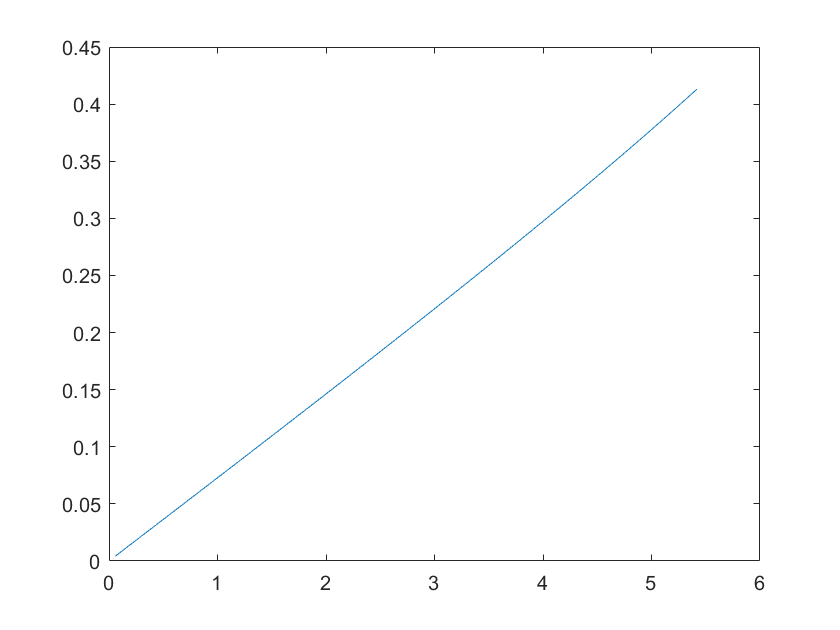

plot(alpha.*180./pi,Cl)     % asse x angolo d'attacco; asse y Cl

Grafico che mostra l'andamento del coefficiente di drag in funzione dell'angolo di attacco

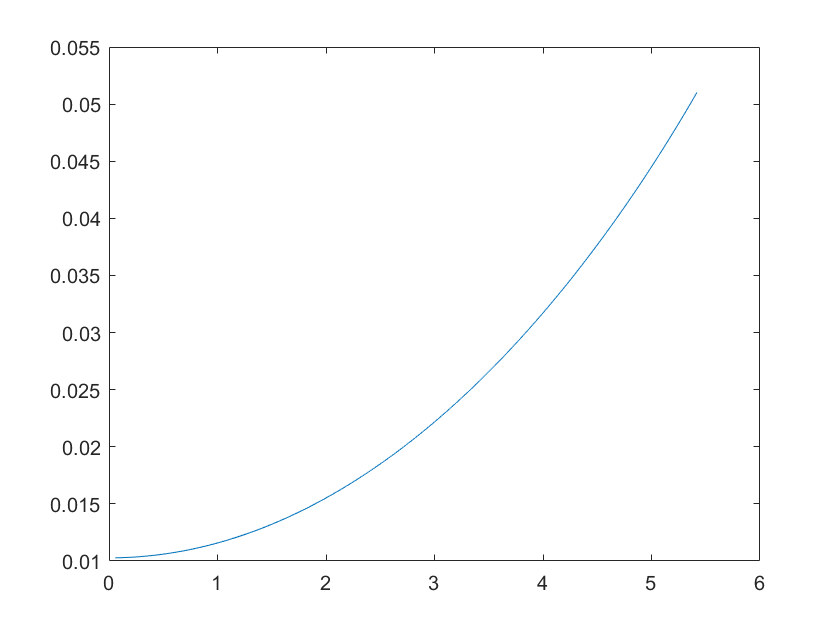

plot(alpha.*180./pi,Cd)     % asse x angolo d'attacco; asse y Cd

Grafico che mostra l'andamento dell'efficienza aerodinamica in funzione dell'angolo di attacco

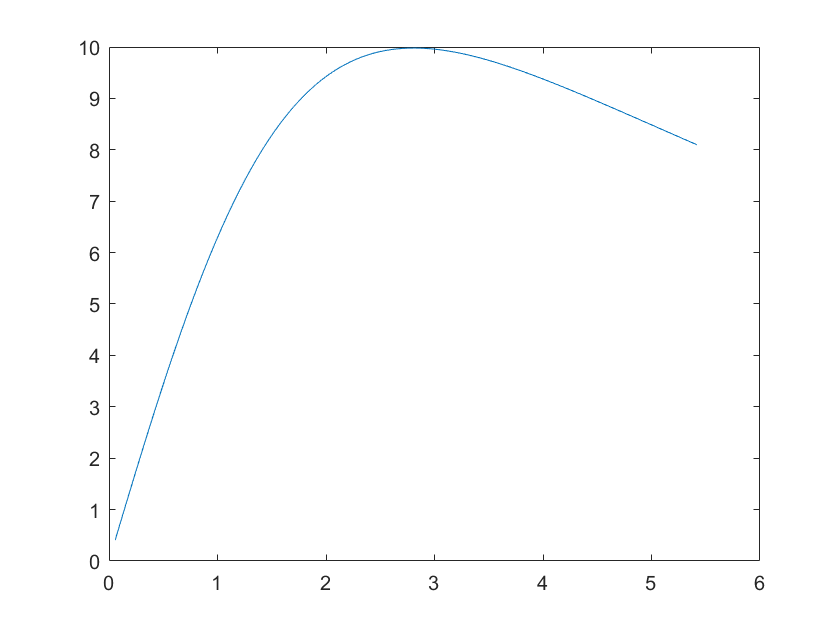

plot(alpha.*180./pi,Cl./Cd)  % asse x angolo d'attacco; asse y efficienza aerodinamica

% Parte seconda:
% visto che esiste un massimo dell'efficienza è possibile chiedersi come
% questa vari in funzione del numero di Mach
 
clear
clc


gamma = 1.4;
M = linspace(1.4,10,100);               % vettore del numero di Mach
p = 1e5;
T = 280;
c = 1;
t_perc = 5;    % spessore del profilo come percentuale della corda (es 5% -> lo spessore massimo è il 5% della corda)

t = t_perc/100*c;
epsilon = atan(t/c);

alpha1 = theta_max(M,gamma) -epsilon - 0.02;
alpha = [];
for i = [1:length(alpha1)]
    if alpha1(i) > 20 *pi/180
        alpha1(i) = 20 *pi/180;
    end
    alpha(i,:) = linspace(0.001,alpha1(i),100);
end

Eff = [];
for i = [1:length(M)]
    
    [L,D,Cl,Cd] = profilo_supersonico(alpha(i,:),epsilon,p,T,M(i),gamma,c);
    Eff(i) = max(Cl./Cd);
end


Valore di Massima efficienza aerodinamica in funzione del numero di Mach

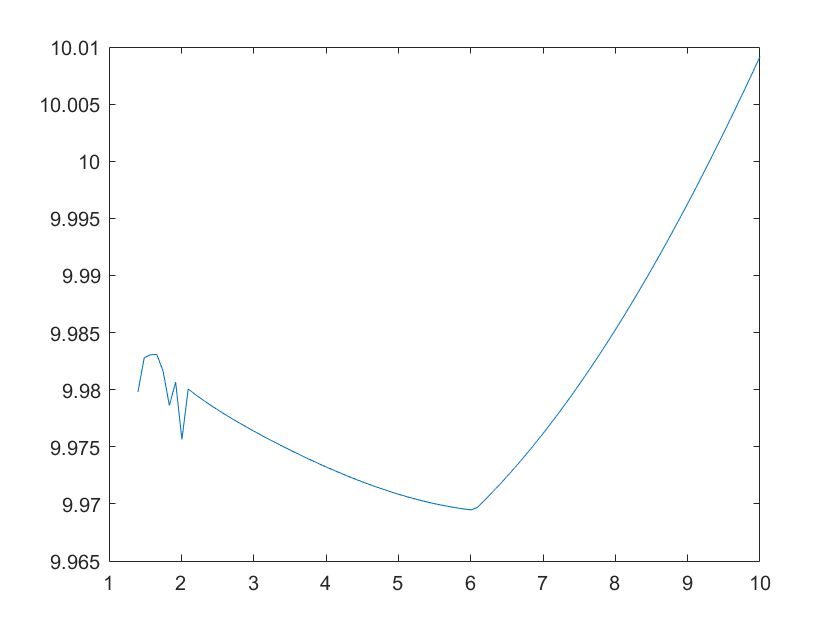

plot(M,Eff)    % asse x numero di Mach; asse y efficienza: non si ha un grande cambiamento al variare di mach